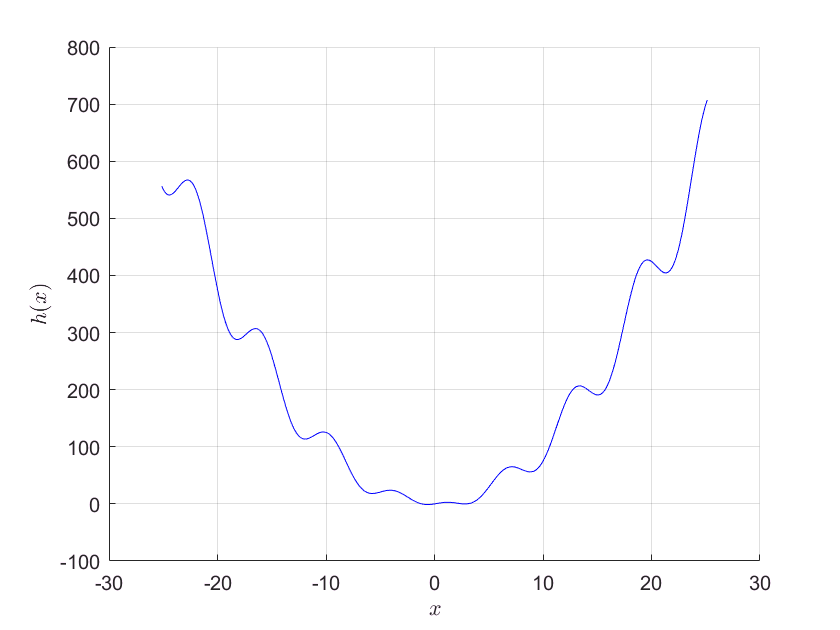

plot_function()

x_sga = -11.9264

h_sga = 113.5400

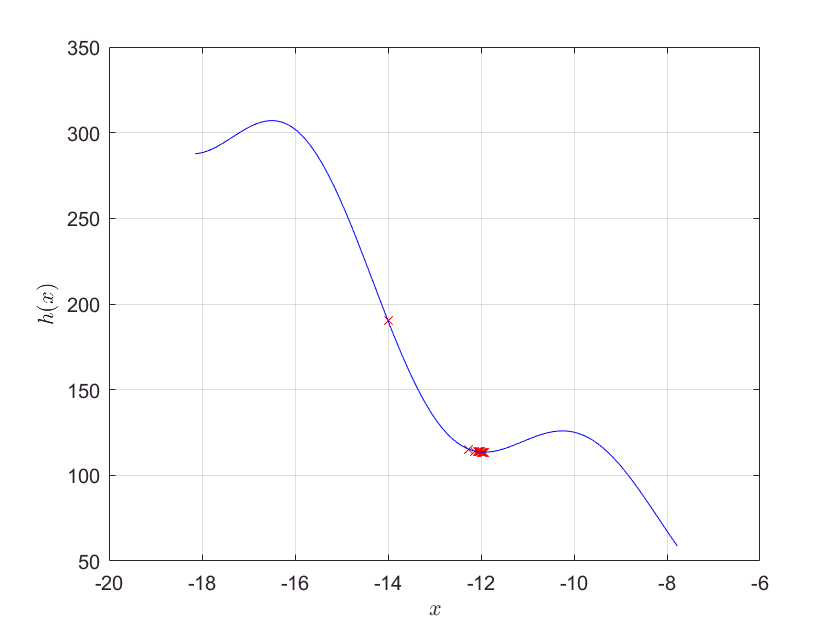

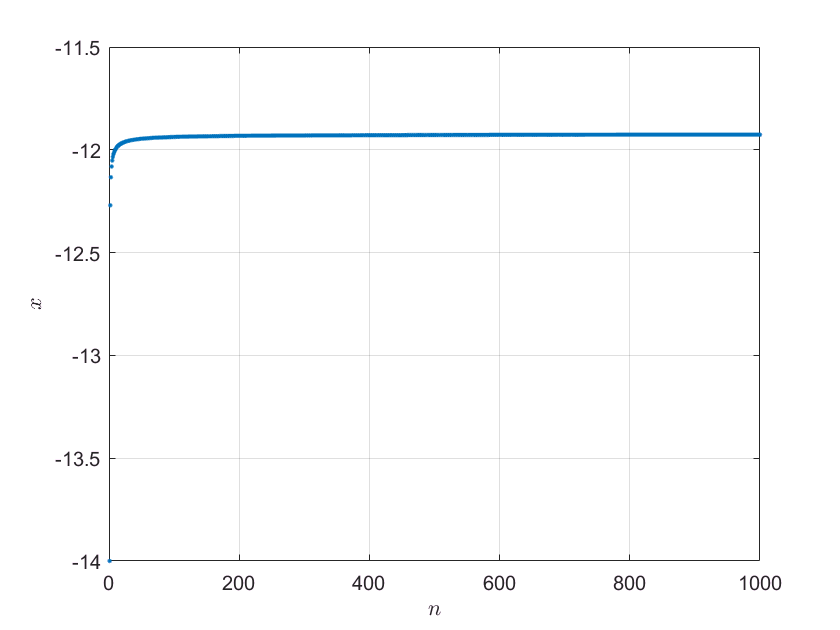


N = 1000; % Number of repetitions
x_0 = -14; % Initial point
alpha = 0.025;
factor_delta = 5; % Size window > 1
[x_sga,h_sga] = sga(N,x_0,alpha,factor_delta)

ans = 0.1419

ans = 0.4218

x_saa = 0

h_saa = 0

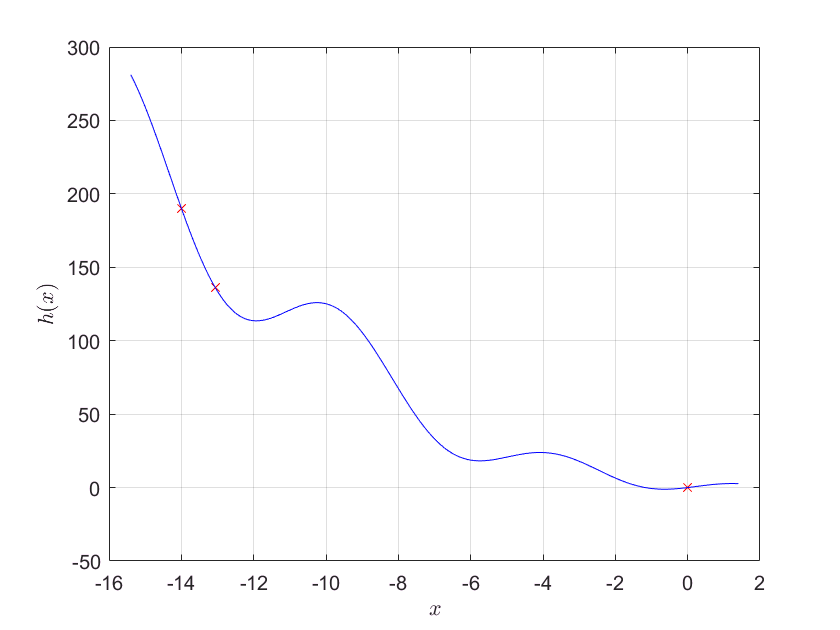

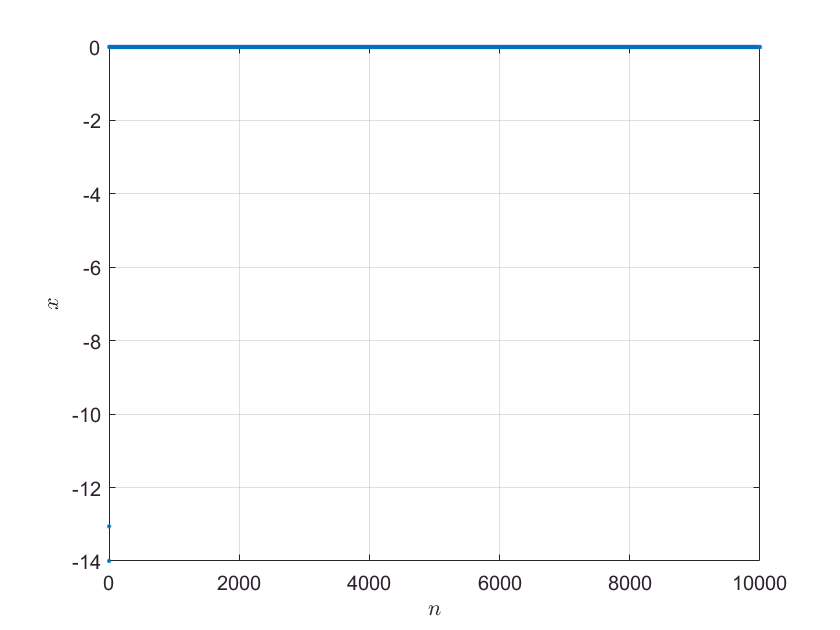


factor_delta = 1.2; % Size window > 1
[x_saa,h_saa] = saa(N,x_0,factor_delta)

function [x_sga,h_sga] = sga(N,x_0,alpha,factor_delta)
    switch nargin
        case 0
            N = 1000;
            x_0 = 0.75;
            alpha = 0.025;
            factor_delta = 3;
        case 2
            alpha = 0.025;
            factor_delta = 3;
        case 3
            factor_delta = 3;
    end
    x_n = zeros(1,N);
    x_n(1) = x_0;
    for i=1:N-1
        gh = x_n(i)*(2-3*sin(x_n(i)))+3*cos(x_n(i));
        x_n(i+1) = x_n(i) - alpha/i * gh;
    end
    h_n = x_n.*(x_n+3*cos(x_n));
    plot_function(x_n,h_n,factor_delta);
    x_sga = x_n(end);
    h_sga = h_n(end);
end

function [x_saa,h_saa] = saa(N,x_0,factor_delta)
    switch nargin
        case 0
            N = 1000;
            x_0 = (rand*16 - 8)*pi;
            factor_delta = 1.2;
    end
    T_0 = 10000;
    N = 10000;
    alpha = 0.999;
    x_n = zeros(1,N);
    x_n(1) = x_0;
    for i=1:1
        z = x_n(i) + (rand -0.5)*pi; %our uniform disftibution (proposed)
        h_z = z*(z+3*cos(z));
        h_x_n = x_n(i)*(x_n(i)+3*cos(x_n(i)));
        if h_z <= h_x_n
            x_n(i+1) = z;
        else
            delta_h = h_z - h_x_n;
            T_n = T_0*alpha^i;
            if exp(-delta_h/T_n) > rand
                x_n(i+1) = z;
            else
                x_n(i+1) = x_n(i);
            end
        end
    end
    h_n = x_n.*(x_n+3*cos(x_n));
    plot_function(x_n,h_n,factor_delta);
    x_saa = x_n(end);
    h_saa = h_n(end);
end

function plot_function(x_n,h_n,factor_delta)
    switch nargin
        case 0
            xi = -8*pi;
            xf = 8*pi;
        case 3
            min_x = min(x_n);
            max_x = max(x_n);
            delta = (max_x - min_x)*(factor_delta-1)/2;
            xi = min_x - delta;
            xf = max_x + delta;
            plot(x_n,h_n,'xr');
    end
    N = 1000;
    x = linspace(xi,xf,N);
    h = x.*(x+3*cos(x));
    hold on; grid on; plot(x,h,'b'); hold off;    
    xlabel("$x$",'Interpreter','latex');
    ylabel("$h(x)$",'Interpreter','latex');
    if nargin == 3
        figure; plot(x_n,'.'); grid on; hold on;
        %m = islocalmin(h);
        %for i=1:N
        %    if m(i) == 1
        %       line([1 1000],[x(i) x(i)],'Color','red','LineStyle','--');
        %    end
        %end
        hold off;
        xlabel("$n$",'Interpreter','latex');
        ylabel("$x$",'Interpreter','latex');
    end
end